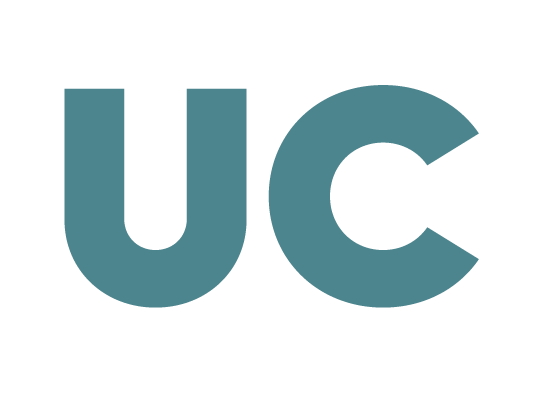

***Grado de Tecnologías de Telecomunicación***

**G282: Álgebra y Geometria**

# **Práctica 4: Espacios vectoriales**

*Dpto. Matemática Aplicada y Ciencias de la Computación*

**Objetivos**

- Determinar si un conjunto de vectores es libre o ligado

- Obtener una base de un subespacio

**Funciones de MATLAB utilizadas en este guion: **`rank, null, rref`

format rat
clear all;

## **Dependencia e independencia lineal**

### **Método 1****: matriz escalonada **

Sea el conjunto de vectores $$S=\lbrace (5,-9,6,4), (-3,4,-2,-1), (0,-7,8,7), (2,0,4,1)\rbrace$$de $\mathbb{R}^4$. Sabemos que el conjunto $S$ será libre (o linealmente independiente) si la única manera de expresar el vector  nulo  como combinación lineal de los vectores de $S$ es que todos los coeficientes de la combinación lineal sean nulos. Esto equivale a comprobar que el sistema homogéneo que tiene por matriz  de coeficientes $A$ los vectores de $S$, colocados por columnas, tenga tan sólo la solución trivial (si tuviera infinitas soluciones, $S$ sería un conjunto ligado).


$$
\alpha_1
\left(\begin{array}{c}
     5\\  
     -9\\  
     6\\  
     4\end{array}\right)
+\alpha_2\left(\begin{array}{c}
     -3\\  
     4\\  
     -2\\  
     -1\end{array}\right)
+\alpha_3 \left(\begin{array}{c}
     0\\  
     -7\\  
     8\\  
     7\end{array}\right)
+\alpha_4\left(\begin{array}{c}
     2\\  
     0\\  
     4\\  
     1\end{array}\right)=
\left(\begin{array}{cccc}
     5 & -3 & 0 & 2\\  
     -9 & 4 & -7 & 0\\  
     6 & -2 & 8 & 4\\  
     4 & -1 & 7 & 1\end{array}\right)
\left(\begin{array}{cccc}
     \alpha_1 \\  
   \alpha_2 \\  
     \alpha_3\\  
     \alpha_4\end{array}\right)
=\left(\begin{array}{cccc}
    0 \\  
   0 \\  
     0\\  
     0\end{array}\right)$$


En realidad, para estudiar la dependencia de un conjunto de vectores estudiamos el tipo de solución de un sistema lineal homogéneo. Los sistemas homogéneos siempre son compatibles, luego únicamente es necesario estudiar si el sistema es SCI (vectores ligados) o SCD (vectores libres). Luego bastará con comprobar si el rango de la matriz de vectores por columnas coincide o no con el número de vectores del conjunto (columnas de A). 

% defino los vectores del conjunto
u1 = [5 -9 6 4]';
u2 = [-3 4 -2 -1]';
u3 = [0 -7 8 7]';
u4 = [2 0 4 1]';

% clasifico el sistema homogéneo de interés
A = [u1 u2 u3 u4]  % matriz de coefs. 
rank(A)  % R-F: S.C.I. -> el conjunto S es ligado

El comando *rank *nos indica cuál es el número de vectores independientes. En este caso tenemos 4 vectores y rango 3, luego el conjunto de 4 vectores es ligado, por lo que sabemos que al menos un vector puede expresarse como combinación lineal del resto de vectores. El rango de 3 nos indica que el mayor subconjunto libre de vectores de S que podemos escoger es de 3 vectores. Pueden existir varios grupos de 3 vectores libres. Una manera fácil de encontrar un grupo de 3 vectores libres es a través de la escalonada reducida de la matriz que forman los vectores al colocarlos por columnas, los vectores de las columnas pivotales formarán un conjunto libre. 

rref(A)  % identifico u1, u2 y u4 como L.I. (columnas pivotales)

Las columnas pivotales son la 1, 2 y 4. Luego los vectores $$S=\lbrace (5,-9,6,4), (-3,4,-2,-1),  (2,0,4,1)\rbrace$$forman un conjunto libre y por tanto deberán tener rango 3. Vamos a comprobarlo:

rank(A(:,[1 2 4]))%subconjunto de 3 vecotres l.i. (u1, u2 y u4)

Además de permitirnos identificar rápidamente un subconjunto de vectores libres, la matriz escalonada reducida también nos da información de las relaciones de dependencia de los vectores de un conjunto. Al tratarse $S$ de un conjunto ligado, esto nos asegura que algunos de los vectores pueden expresarse como C.L. del resto. Específicamente, las columas no pivotales nos permiten identificar cómo los vectores de columnas no pivotales se pueden obtener como combinación lineal de los vectores de las columnas pivotales. En este ejemplo la única columna no pivotal (la tercera) es el vector [3 5 0 0] y podemos observar fácilmente en la matriz escalonada reducida que este vector se obtiene así: multiplicando la primera columna por 3 y sumando la segunda columna multiplicada por 5. Comprobémoslo:

% podemos expresar el vector u3 como combinación lineal del resto:
u3
3*u1+5*u2

***Nota******:*** *Siempre colocaremos los vectores de cualquier conjunto del que queramos estudiar su dependencia/independencia lineal en columnas. Esto es importante ya que al escalonar la matriz las relaciones entre los vectores de las columnas se mantienen (pero esto no es así para los vectores fila).*

### **Método 2: resolución sistema lineal homogéneo**

Otro método para hallar las relaciones de dependencia de un conjunto de vectores es resolviendo el sistema lineal homogéneo $A\vec{x}=\vec{0}$, donde $A$ es la matriz con los vectores del conjunto en columas. 


$$
\alpha_1
\left(\begin{array}{c}
     5\\  
     -9\\  
     6\\  
     4\end{array}\right)
+\alpha_2\left(\begin{array}{c}
     -3\\  
     4\\  
     -2\\  
     -1\end{array}\right)
+\alpha_3 \left(\begin{array}{c}
     0\\  
     -7\\  
     8\\  
     7\end{array}\right)
+\alpha_4\left(\begin{array}{c}
     2\\  
     0\\  
     4\\  
     1\end{array}\right)=
\left(\begin{array}{cccc}
     5 & -3 & 0 & 2\\  
     -9 & 4 & -7 & 0\\  
     6 & -2 & 8 & 4\\  
     4 & -1 & 7 & 1\end{array}\right)
\left(\begin{array}{cccc}
     \alpha_1 \\  
   \alpha_2 \\  
     \alpha_3\\  
     \alpha_4\end{array}\right)
=\left(\begin{array}{cccc}
    0 \\  
   0 \\  
     0\\  
     0\end{array}\right)$$


Para resolver sistema lineales homogéneos el comándo `null` nos será muy útil. Como ya hemos visto, si el sistema es SCD (y por tanto el conjunto de vectores fuera libre) entonces solo tendrá la solución trivial y `null` nos devolvería un vector vacío. Para SCI como este ejemplo, la función `null` nos dará un vector por cada parámetro libre.

rank(A)%SCI, 1 parámetro libre
null(A, 'rational') % relación de dependencia: -3*u1-5*u2+1*u3+0*u4 = 0

La solución del sistema lineal homogéneo son las combinaciones lineales de los vectores devueltos por la función `null`. En este ejemplo:


$$\left(\begin{array}{cccc}
     \alpha_1 \\  
   \alpha_2 \\  
     \alpha_3\\  
     \alpha_4\end{array}\right)=
\lambda \left(\begin{array}{cccc}
    -3 \\  
   -5 \\  
    1\\  
     0\end{array}\right)$$


El SCI tiene infinitas soluciones, dando el valor $\lambda=1
$ obtenemos una de ellas:


$$
-3
\left(\begin{array}{c}
     5\\  
     -9\\  
     6\\  
     4\end{array}\right)
-5\left(\begin{array}{c}
     -3\\  
     4\\  
     -2\\  
     -1\end{array}\right)
+1 \left(\begin{array}{c}
     0\\  
     -7\\  
     8\\  
     7\end{array}\right)
+0\left(\begin{array}{c}
     2\\  
     0\\  
     4\\  
     1\end{array}\right)
=\left(\begin{array}{cccc}
    0 \\  
   0 \\  
     0\\  
     0\end{array}\right)$$


Es decir $-3\vec{u_1} -5\vec{u_2} +1\vec{u_3} +0\vec{u_4}=\vec{0}$. Claramente vemos que podemos expresar unos vectores como C.L. de otros del conjunto, por lo que el conjunto es ligado. Por ejemplo, podemos expresar el tercer vector como C.L de los dos primeros $\vec{u_3} =+3\vec{u_1} +5\vec{u_2} $

## Ejercicios propuestos

**Ejercicio 1:**

Comprueba si los siguientes conjuntos de vectores de $\mathbb{R}^5$ son libres o ligados. 

- *a)* $A = \lbrace (1,0,1,2,1), (0,1,0,-1,3), (1,0,-1,0,5) \rbrace$

- *b)* $B = \lbrace (-2,4,0,-1,2), (2,1,2,-1,-1), (1,0,2,1,0), (0,1,-2,-3,1) \rbrace$

**Solución 1:**

A = [1 0 1 2 1; 0 1 0 -1 3; 1 0 -1 0 5]';  % vectores en columnas
rank(A)  % rango máximo --> conjunto libre
null(A, 'r')  % sólo existe sol. trivial --> conjunto libre

B = [-2 4 0 -1 2; 2 1 2 -1 -1; 1 0 2 1 0; 0 1 -2 -3 1]';  % vectores en columnas
rank(B)  % rango máximo --> conjunto libre
null(B, 'r')  % sólo existe sol. trivial --> conjunto libre

**Ejercicio 2:**

Encuentra las relaciones de dependencia lineal (en caso de haberlas) que se dan en el conjunto de vectores $S=\lbrace \vec{u_1}, \vec{u_2}, \vec{u_3}, \vec{u_4} \rbrace$, siendo $\vec{u_1}=(1,0,1,2)$,  $\vec{u_2}=(0,1,1,1)$,  $\vec{u_3}=(4,3,7,11)$ y  $\vec{u_4}=(-2,1,-1,-3)$. Comprueba que son correctas.

% defino los vectores de S
u1 = [1 0 1 2]';
u2 = [0 1 1 1]';
u3 = [4 3 7 11]';
u4 = [-2 1 -1 -3]';
S = [u1 u2 u3 u4];  % conjunto de vectores S

% Resolvemos el sistema lineal homogéneo cuya matriz de coeficientes es S
null(S, 'r')
% por tanto, dos de las infinitas relaciones de dependencia serían -4*u1-3*u2+u3=0 y 
% 2*u1-u2+u4=0. Cualquier combinación lineal de las dos columnas obtenidas
% en el null nos proporcionara unos coeficientes que expresan la relación de dependencia 

**Ejercicio 3:**

Dado el conjunto de vectores $S=\lbrace (1,0,-3,2), (0,1,2,-3), (-3,-4,1,6), (1,-3,-8,7), (2,1,-6,9) \rbrace$de $\mathbb{R}^4$. Halla las relaciones de dependencia que se establecen entre los vectores de $S$.

S = [1 0 -3 2; 0 1 2 -3; -3 -4 1 6; 1 -3 -8 7; 2 1 -6 9]';  % vectores de S 
rank(S)  % sólo hay 3 vectores L.I. -> S es un conjunto ligado
null(S, 'r')
% por tanto, dos de las infinitas relaciones de dependencia serían -3*u1-4*u2+u3=0 y 
% -4*u1+5u2+2u4+u5=0. Cualquier combinación lineal de las dos columnas obtenidas
% en el null nos proporcionara unos coeficientes que expresan la relación de dependencia 